%% plot_density_y33.m
% Plots the density slice at y = 33 m (t = 120 s) using the CORRECT,
% grid-consistent row index, overlaid with the paper's digitized data.
%
% Fixes the earlier bug where y_plot = linspace(0,Ly,Ny-6) (spacing
% 50/49 instead of h=1) caused the "nearest point" search to pick
% row 36 (raw index -> physical y=32) instead of the true y=33 row.

clear all; clc;

%% --- Load the reproduced density data (stripped array, no ghost points) ---
% rho_at_120s = rho(4:Ny-3, 4:Nx-3) from the solver, size (Ny-6) x (Nx-6)
rho_at_120s = readmatrix('Rho_at_120.xlsx');   % expect 50 x 100

[Ny_interior, Nx_interior] = size(rho_at_120s);
fprintf('Loaded rho_at_120s: %d x %d (rows=y, cols=x)\n', Ny_interior, Nx_interior);

Loaded rho_at_120s: 50 x 100 (rows=y, cols=x)



%% --- Domain parameters (must match the solver) ---
Lx = 100;
Ly = 50;
h  = Lx / Nx_interior;      % = 1 for this problem
% Sanity check: the y-direction should use the SAME h
h_y_check = Ly / Ny_interior;
if abs(h - h_y_check) > 1e-9
    warning('x and y grid spacing do not match (h=%.6f vs %.6f). Check Nx/Ny/Lx/Ly.', h, h_y_check);
end

%% --- Grid-consistent coordinate vectors (NO linspace stretching!) ---
% x_plot(k) = (k-1)*h exactly matches the physical location of column k
x_plot = (0:Nx_interior-1) * h;   % 0, 1, 2, ..., 99
y_plot = (0:Ny_interior-1) * h;   % 0, 1, 2, ..., 49

%% --- Pick the rows for y = 32, 33, 34 using the exact grid mapping ---
y_targets = [32, 33, 34];
row_idx   = round(y_targets/h) + 1;     % = [33, 34, 35] when h = 1

for k = 1:numel(y_targets)
    fprintf('Using row %d -> y = %.4f (target was y = %g)\n', ...
        row_idx(k), y_plot(row_idx(k)), y_targets(k));
end

Using row 33 -> y = 32.0000 (target was y = 32)
Using row 34 -> y = 33.0000 (target was y = 33)
Using row 35 -> y = 34.0000 (target was y = 34)


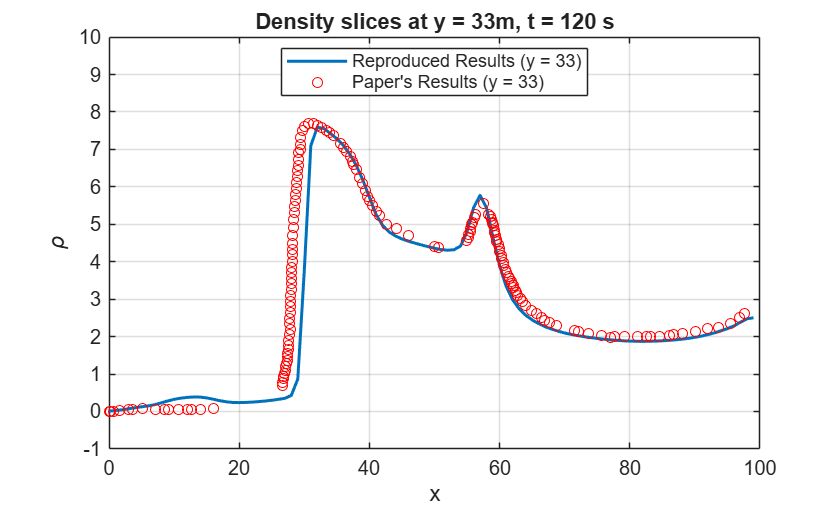


rho_at_32 = rho_at_120s(row_idx(1), :);
rho_at_33 = rho_at_120s(row_idx(2), :);
rho_at_34 = rho_at_120s(row_idx(3), :);

%% --- Load the paper's digitized reference data (for y = 33 only) ---
paper   = readtable('Density_At_33_Paper_Result.csv');
x_csv   = paper.x;
rho_csv = paper.rho;

%% --- Plot all slices + paper data on the same axes ---
figure;
plot(x_plot, rho_at_33, '-', 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]); hold on;   % original/corrected y=33 (unchanged)
plot(x_csv, rho_csv, 'ro', 'MarkerSize', 5);                                           % paper's results (unchanged)

xlabel('x');
ylabel('\rho');
title('Density slices at y = 33m, t = 120 s');
legend('Reproduced Results (y = 33)', "Paper's Results (y = 33)", ...
    'Location', 'best');
xlim([0 Lx]);
ylim([-1 10]);
grid on;
hold off;